clc
clear

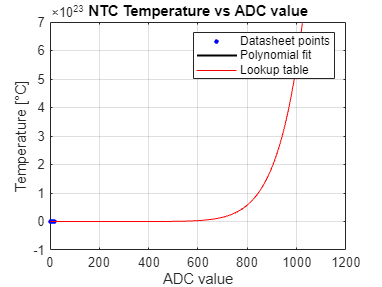

data = csvread('ntc.csv');

t = data(:,1);      % temperature [°C]
r = data(:,2);      % resistance [ohms]

%% 2. Calculate ADC values from resistance
R5 = 10000;         % fixed resistor 10kΩ
ADC_MAX = 1024;     % 10-bit ADC range

% Voltage divider:
% Vadc = Vref * (Rntc / (Rntc + R5))
% ADC value = (Rntc / (Rntc + R5)) * ADC_MAX
ad = ADC_MAX * (r ./ (r + R5));

%% 3. Plot temperature vs ADC value
figure;
plot(ad, t, 'b.', 'MarkerSize', 10);
grid on;
xlabel('ADC value');
ylabel('Temperature [°C]');
title('NTC Temperature vs ADC value');

%% 4. Polynomial approximation
% High-order polynomial fit (order 10)
p = polyfit(ad, t, 10);

% Plot polynomial curve
ad_fit = linspace(min(ad), max(ad), 1000);
t_fit = polyval(p, ad_fit);
hold on;
plot(ad_fit, t_fit, 'k-', 'LineWidth', 1.5);
legend('Datasheet points', 'Polynomial fit');

%% 5. Generate full ADC lookup table
ad2 = 0:1023;                       % ADC index values
t2 = round(polyval(p, ad2), 1);     % temperature rounded to 0.1 °C

% Plot lookup table result
plot(ad2, t2, 'r');
legend('Datasheet points', 'Polynomial fit', 'Lookup table');


%% 6. Export table for C language
% Store temperature in tenths of a degree
% Example: 23.4 °C -> 234
dlmwrite('data.dlm', t2 * 10, ',');

disp('Lookup table successfully generated: data.dlm');

Lookup table successfully generated: data.dlm
